# Final Project Module 3 

Student Name : Dhia ZNAIDI

## Segment the Foreground

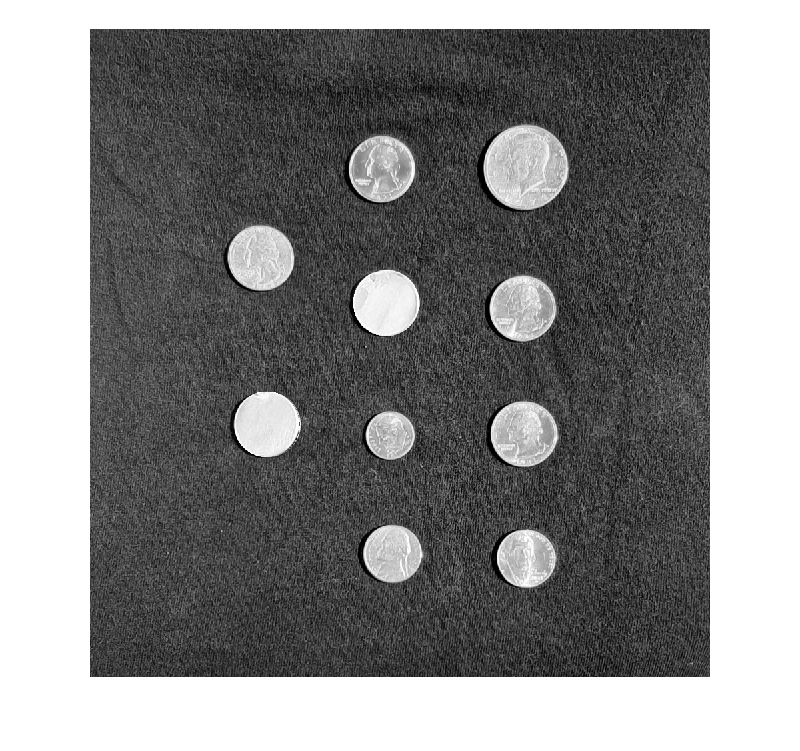

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure, imshow(testCoinImage)

Let's apply the mask function

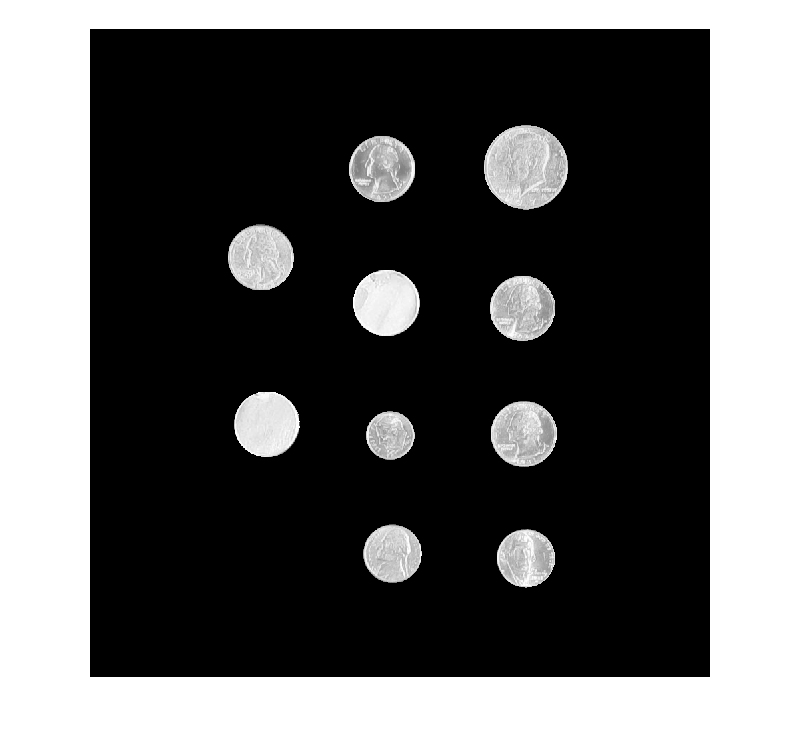

[testCoinMask,maskedTestCoinImage] = segmentBinary(testCoinImage);
imshow(maskedTestCoinImage)

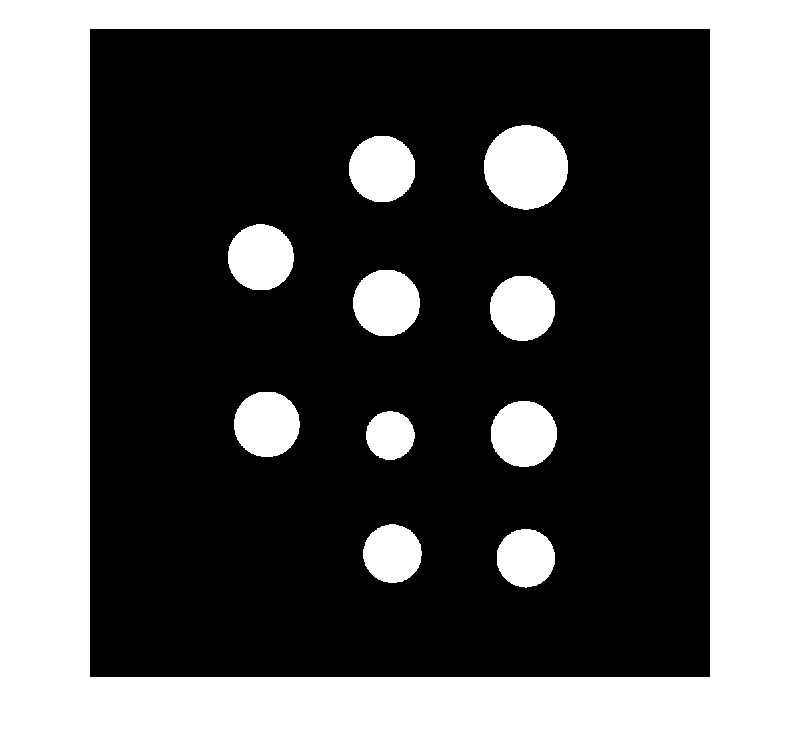

imshow(testCoinMask)

## Valid Coin Face Edges

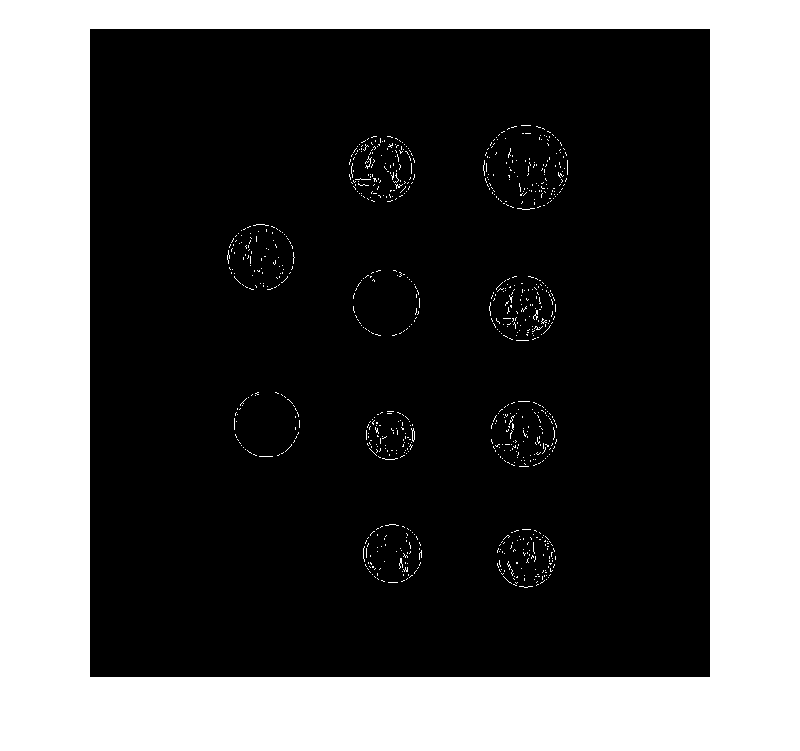

imgAdv = im2gray(maskedTestCoinImage);
gaussfilt = imgaussfilt(imgAdv,0.5);
edged_coins = edge(gaussfilt,"sobel",0.07);
imshow(edged_coins)

Let's erode the maskedImage to reduce the radius of the coins 

[BW,maskedImage] = erosion(maskedTestCoinImage);
faceEdgeMask= BW & edged_coins ; 

## Valid Coin segmentation

For this problem the code will need to create a mask which completely segments *only* the valid coins. 

The solutions to the previous assignments include a foreground mask with true pixel regions where any circular object is present (`testCoinMask`), and another coin face edge mask with true pixels only within the regions of valid coins (`faceEdgeMask`). Therefore, one approach to this task is to dilate the true pixel regions in `faceEdgeMask` to be greater than or equal to the size of the corresponding foreground regions in `testCoinMask`, and logically combine the result with `testCoinMask` to extract the valid coin regions. 

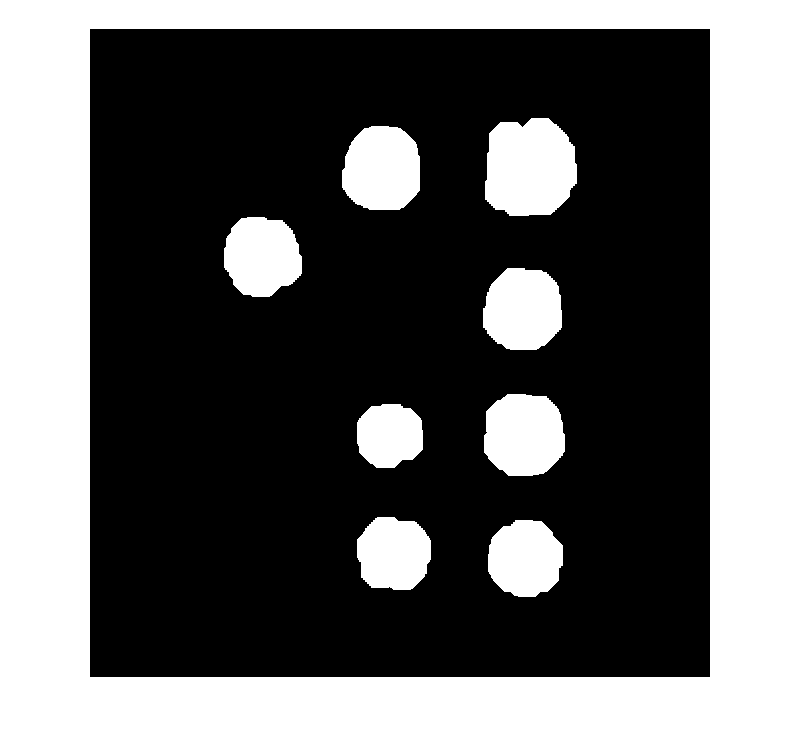

se = strel('disk',30);
faceEdgeMask_task= imdilate(faceEdgeMask, se);
imshow(faceEdgeMask_task)

Let's combine this result with the foreground mask

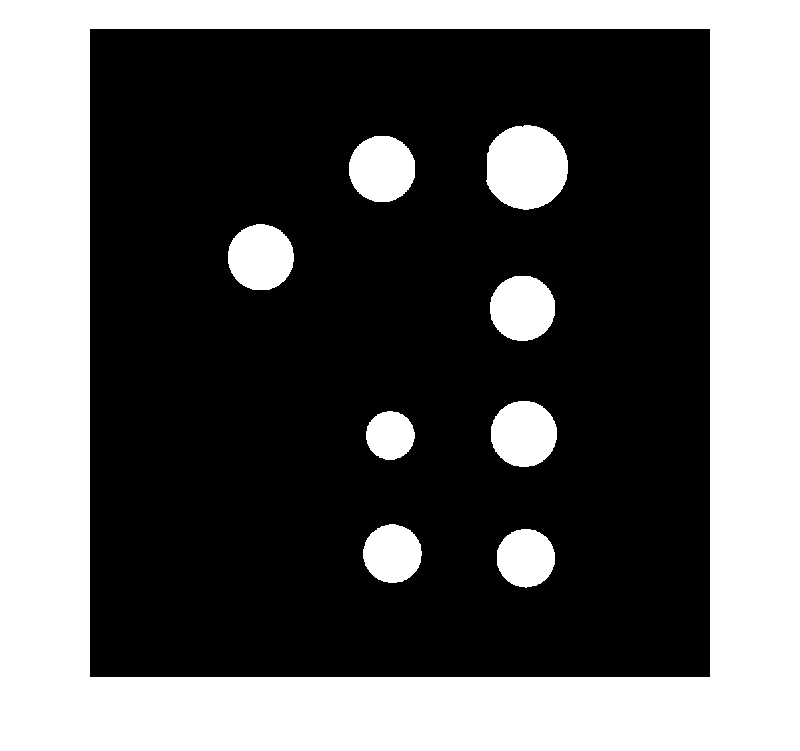

validCoinMask = testCoinMask & faceEdgeMask_task;
imshow(validCoinMask)

Now let's count 

## Final Analysis

[coin_mask,coinSizes] =  filterCoins(validCoinMask);
coinSizes = sortrows(coinSizes, "Area");

nDimes = sum(coinSizes.Perimeter < 260)

nDimes = 1

nNickels = sum((coinSizes.Perimeter > 270) & (coinSizes.Perimeter < 300) ) 

nNickels = 2

nQuarters = sum((coinSizes.Perimeter > 300) & (coinSizes.Perimeter < 320) )

nQuarters = 4

nFiftyCents = sum(coinSizes.Perimeter >350)

nFiftyCents = 1

USD = nDimes * 0.1 + nNickels * 0.05 + nQuarters * 0.25 + nFiftyCents * 0.5

USD = 1.7000